# EE 146: Computer Vision

# Buddy Ugwumba SID: 862063029

# Lab 9: Texture Descriptors

# Date: 03/02/2022

**Goal: **Understand co-occurrence matrices as a characteristic of texture in images. 

**Problem 1: ****Co-occurrence matrices and features**		

A co-occurrence matrix is a two-dimensional array C in which both the rows and the columns represent a set of possible image values V. Co-occurrence matrix **C(i, j) **indicates how many times gray scale value **i **co-occurs with gray scale value **j **in some designated spatial relationship d. d is a displacement vector **(dr, dc) **where **dr **is a displacement in rows and **dc **is a displacement in columns. 

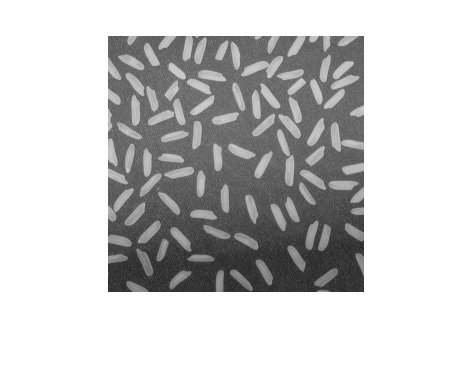

% Get image
I = imread('rice.png');
imshow(I)


% Compute co-occurence Matrix D(1,2)
glcm1 = graycomatrix(I,'Offset',[1 2])

glcm1 =            0           0           0           0           0           0           0           0
           0        7764        1053         171         127           0           0           0
           0        1206        9251        2266         488         196           1           0
           0         189        2303       19130        1150        1839         241           0
           0         164         480        1129        2189         767         146           0
           0           0         289        1809         815        6014         919           0
           0           0           0         310         136         899        1329           0
           0           0           0           0           0           0           0           0


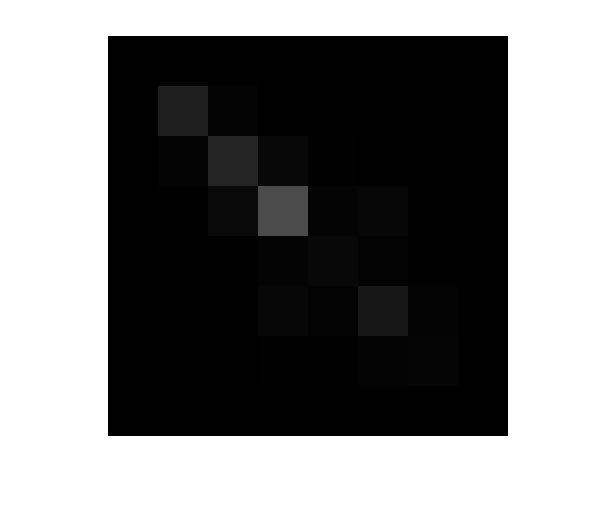

    % Normalize the matrix
    total = 0;
    total_entropy1 = 0;
    for i = 1:size(glcm1,1)
        for j = 1:size(glcm1,2)
            value = glcm1(i,j);
            total = total+value;
        end
    end
    glcm1_1 = glcm1/total;
    imshow(glcm1_1, "InitialMagnification", 5000)

        % Compute energy
            energy1 = graycoprops(glcm1, 'Energy')

energy1 = struct with fields:
    Energy: 0.1384


        % Compute entropy
            for i = 1:size(glcm1_1,1)
                for j = 1:size(glcm1_1,2)
                    value = glcm1_1(i,j);
                    if value ~= 0
                        entropy = -value*log(value);
                        total_entropy1 = total_entropy1 + entropy;
                    end
                end
            end
            total_entropy1

total_entropy1 = 2.5032

        % Compute contrast
            contrast1 = graycoprops(glcm1, 'Contrast')

contrast1 = struct with fields:
    Contrast: 0.7025


        % Compute correlation
            correlation1 = graycoprops(glcm1, 'Correlation')

correlation1 = struct with fields:
    Correlation: 0.8075


        
        
% Compute co-occurence Matrix D(2,2)
glcm2 = graycomatrix(I,'Offset',[2 2])

glcm2 =            0           0           0           0           0           0           0           0
           0        7470        1072         215         155           0           0           0
           0        1399        8633        2445         624         290           2           0
           0         228        2640       18238        1138        2214         377           0
           0         226         589        1131        2000         743         167           0
           0           0         393        2209         829        5479         936           0
           0           0           0         454         148         928        1144           0
           0           0           0           0           0           0           0           0


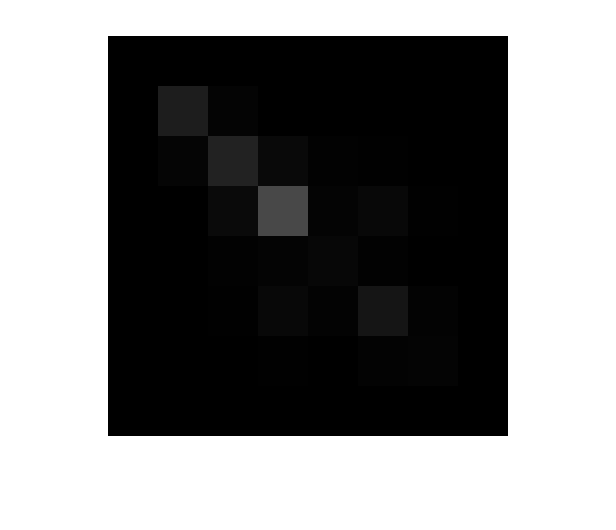

    % Normalize the matrix
    total = 0;
    total_entropy2 = 0;
    for i = 1:size(glcm2,1)
        for j = 1:size(glcm2,2)
            value = glcm2(i,j);
            total = total+value;
        end
    end
    glcm2_2 = glcm2/total;
    imshow(glcm2_2, "InitialMagnification", 5000)

        % Compute energy
            energy2 = graycoprops(glcm2, 'Energy')

energy2 = struct with fields:
    Energy: 0.1276


        % Compute entropy
            for i = 1:size(glcm2_2,1)
                for j = 1:size(glcm2_2,2)
                    value = glcm2_2(i,j);
                    if value ~= 0
                        entropy = -value*log(value);
                        total_entropy2 = total_entropy2 + entropy;
                    end
                end
            end
            total_entropy2

total_entropy2 = 2.5846

        % Compute contrast
            contrast2 = graycoprops(glcm2, 'Contrast')

contrast2 = struct with fields:
    Contrast: 0.8668


        % Compute correlation
            correlation2 = graycoprops(glcm2, 'Correlation')

correlation2 = struct with fields:
    Correlation: 0.7622


        
        
% Compute co-occurence Matrix D(2,3)
glcm3 = graycomatrix(I,'Offset',[2 3])

glcm3 =            0           0           0           0           0           0           0           0
           0        7284        1033         279         285           0           0           0
           0        1382        8427        2301         736         497           2           0
           0         280        2511       17341        1145        2843         609           0
           0         349         717        1134        1721         704         198           0
           0           0         585        2898         798        4611         924           0
           0           0           4         671         179         937         877           0
           0           0           0           0           0           0           0           0


    % Normalize the matrix
    total = 0;
    total_entropy3 = 0;
    for i = 1:size(glcm3,1)
        for j = 1:size(glcm3,2)
            value = glcm3(i,j);
            total = total+value;
        end
    end
    glcm3_3 = glcm3/total

glcm3_3 =          0         0         0         0         0         0         0         0
         0    0.1133    0.0161    0.0043    0.0044         0         0         0
         0    0.0215    0.1311    0.0358    0.0115    0.0077    0.0000         0
         0    0.0044    0.0391    0.2698    0.0178    0.0442    0.0095         0
         0    0.0054    0.0112    0.0176    0.0268    0.0110    0.0031         0
         0         0    0.0091    0.0451    0.0124    0.0718    0.0144         0
         0         0    0.0001    0.0104    0.0028    0.0146    0.0136         0
         0         0         0         0         0         0         0         0


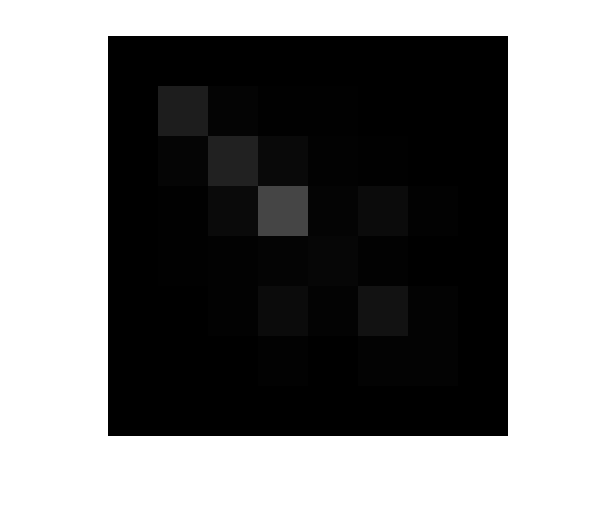

    imshow(glcm3_3, "InitialMagnification", 5000)

        % Compute energy
            energy3 = graycoprops(glcm3, 'Energy')

energy3 = struct with fields:
    Energy: 0.1185


        % Compute entropy
            for i = 1:size(glcm3_3,1)
                for j = 1:size(glcm3_3,2)
                    value = glcm3_3(i,j);
                    if value ~= 0
                        entropy = -value*log(value);
                        total_entropy3 = total_entropy3 + entropy;
                    end
                end
            end
            total_entropy3

total_entropy3 = 2.6617

        % Compute contrast
            contrast3 = graycoprops(glcm3, 'Contrast')

contrast3 = struct with fields:
    Contrast: 1.1274


        % Compute correlation
            correlation3 = graycoprops(glcm3, 'Correlation')

correlation3 = struct with fields:
    Correlation: 0.6907
